# Exerciese

## A.6

Determine the rank of the following matrices

A = [3, 0, 1, 3;
     2, 0, 3, 2;
     0, 2, -8, 1;
     -2, 1, 2, 1];

rank_A = rank(A);
disp(['Rank of the A is ', num2str(rank_A)]);

Rank of the A is 4


## A.20

check if the following systems of equations are consistent. If they are, calculate their general solutions


$$x_1+x_2+x_3+x_4=10\\
-x1+x_2-x_3+x_4=2\\
2x_1-3x_2+2x_3-2x_4=-6$$


A = [1, 1, 1, 1; -1, 1, -1, 1; 2, -3, 2, -2];
b = [10; 2; -6];

Ab = [A, b];
rank_Ab = rank(Ab);
disp(['Rank of the Ab is ', num2str(rank_Ab)]);

Rank of the Ab is 3



% Perform Gaussian elimination to row echelon form
rref_Ab = rref(Ab);

if rank(A) == rank(Ab)
    disp('The system is consistent.');
    disp('General solution:');
    
    % Extract the reduced row echelon form of A and b
    rref_A = rref_Ab(:, 1:end-1);
    rref_b = rref_Ab(:, end);
    
    % Find the particular solution
    particular_solution = rref_A \ rref_b;
    
    % Display the particular solution
    disp(particular_solution);
    
    % Find the null space (homogeneous solution)
    null_space = null(A, 'r');
    
    % Display the null space (homogeneous solution)
    disp('Null space (homogeneous solution):');
    disp(null_space);
    
    % Display the general solution
    disp('General solution:');
    disp(particular_solution + null_space);
else
    disp('The system is inconsistent.');
end

The system is consistent.


General solution:


     4
     2
     0
     4



Null space (homogeneous solution):


    -1
     0
     1
     0



General solution:


     3
     2
     1
     4



## A.29

check the linear independence of the foollowig set of values


$$a^{(1)} =[1,2,3,4,5]^T\\
a^{(2)} =[-2,1,0,1,-1]^T\\
a^{(3)} =[4,0,-3,2,1]^T$$


a1 = [1, 2, 3, 4, 5]';
a2 = [-2, 1, 0, 1, -1]';
a3 = [4,0, -3, 2, 1]';

A = [a1, a2, a3];
rank_A = rank(A);

% check if vector are linearly indepedent
if rank_A == size(A, 2)
    disp('The vectos are linear independent')
else
    disp('The vectors are linearly independent')

end

The vectos are linear independent


## A.32

Find eigenvalues for the following matrices

A = [1, 1, 0;
     1, 4, 0;
     0, 0, 5];

e = eig(A);

disp(e);

    0.6972
    4.3028
    5.0000



# Taylor Series Expansion

1.Write down the taylor series expansion of the funcion about x0.

2. Plot the original function and taylor series expansion near x0.

3. Neglect terms of order three or higher


$$f(x)=x_1e^{-x_1}+x_2+1, x_0=[1,0]^T$$


taylor series expansion for one-dimensional variables

cf) $f(x^*)=\Sigma_{i=0}^{n}\frac{f^n(x^*)}{n!}(x-x^*)^n$

syms x1 x2;

% original function
f1 = @(x1, x2) x1 .* exp(-x1) + x2 + 1;

% taylor series expansion near x0
f2 = @(x1, x2) 2 + ...
               ([exp(-x2); -x1*exp(-x2)+1]' * [x1-1; x2]) + ...
               (1/2 * [x1-1; x2]' * [0, -exp(-x2); -exp(-x2), x1*exp(-x2)] *[x1-1; x2])

f2 = 다음 값을 갖는 function_handle :
    @(x1,x2)2+([exp(-x2);-x1*exp(-x2)+1]'*[x1-1;x2])+(1/2*[x1-1;x2]'*[0,-exp(-x2);-exp(-x2),x1*exp(-x2)]*[x1-1;x2])


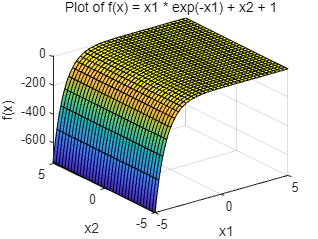


% plot 
figure(1);
fsurf(f1, [-5, 5, -5, 5]);
xlabel('x1');
ylabel('x2');
zlabel('f(x)');
title('Plot of f(x) = x1 * exp(-x1) + x2 + 1');


figure(2);
fsurf(f2, [0.5, 1.5 , -1, 1]);

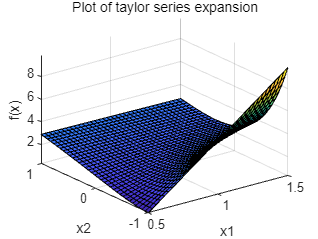

xlabel('x1');
ylabel('x2');
zlabel('f(x)');
title('Plot of taylor series expansion');


result1 = f1(1, 0);
result2 = f2(1, 0);
disp(['Original value: ', num2str(result1)]);

Original value: 1.3679


disp(['Taylor expansion value: ', num2str(result2)]);

Taylor expansion value: 2
